# ACS6116 - Rocket Control - Main

clc; clear; close all;

## Problem Definition

### Define Constants

syms m  % rocket mass
syms g  % gravity (defined as 9.81 further on)  
syms T  % sampling time

### Define Dimensions

syms k;                     % time dimension (discrete)
syms r_x(k) r_y(k) r_z(k);  % rocket coordinates in x,y,z
r = [r_x; r_y; r_z;]        % bold faced vector of coordinates

$$r(k) = \left(\begin{array}{c} r_{x}\left(k\right)\\ r_{y}\left(k\right)\\ r_{z}\left(k\right) \end{array}\right)$$

dim = 3;                    % store the number of spatial dimensions used in the model
syms v_x(k) v_y(k) v_z(k);  % rocket velocity in x,y,z directions
v = [v_x; v_y; v_z;]        % bold faced vector of velocities

$$v(k) = \left(\begin{array}{c} v_{x}\left(k\right)\\ v_{y}\left(k\right)\\ v_{z}\left(k\right) \end{array}\right)$$

### Defining Functions

syms f_x(k) f_y(k) f_z(k);  % thrust in 3 dimensions
f = [f_x; f_y; f_z-m*g]

$$f(k) = \left(\begin{array}{c} f_{x}\left(k\right)\\ f_{y}\left(k\right)\\ f_{z}\left(k\right)-g\,m \end{array}\right)$$

### Rocket Dynamics Model

I = eye(dim);
A = [I, I*T; zeros(dim), I]

$$A = \left(\begin{array}{cccccc} 1 & 0 & 0 & T & 0 & 0\\ 0 & 1 & 0 & 0 & T & 0\\ 0 & 0 & 1 & 0 & 0 & T\\ 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 1 \end{array}\right)$$

B = (1/m)*[0.5*T^2*I; T*I]

$$B = \left(\begin{array}{ccc} \frac{T^{2}}{2\,m} & 0 & 0\\ 0 & \frac{T^{2}}{2\,m} & 0\\ 0 & 0 & \frac{T^{2}}{2\,m}\\ \frac{T}{m} & 0 & 0\\ 0 & \frac{T}{m} & 0\\ 0 & 0 & \frac{T}{m} \end{array}\right)$$

%C = eye(6)
C = [eye(3) zeros(3)]

C =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0



%dynamic_model(k) = [r(k+1); v(k+1);] == A*[r(k); v(k);] + B*f(k)
x(k) = [r(k); v(k);]

$$x(k) = \left(\begin{array}{c} r_{x}\left(k\right)\\ r_{y}\left(k\right)\\ r_{z}\left(k\right)\\ v_{x}\left(k\right)\\ v_{y}\left(k\right)\\ v_{z}\left(k\right) \end{array}\right)$$

x_iterative = A*x(k) + B*f(k)

$$x\_iterative = \begin{array}{l} \left(\begin{array}{c} r_{x}\left(k\right)+T\,v_{x}\left(k\right)+\frac{T^{2}\,f_{x}\left(k\right)}{2\,m}\\ r_{y}\left(k\right)+T\,v_{y}\left(k\right)+\frac{T^{2}\,f_{y}\left(k\right)}{2\,m}\\ r_{z}\left(k\right)+T\,v_{z}\left(k\right)+\frac{T^{2}\,\sigma_{1}}{2\,m}\\ v_{x}\left(k\right)+\frac{T\,f_{x}\left(k\right)}{m}\\ v_{y}\left(k\right)+\frac{T\,f_{y}\left(k\right)}{m}\\ v_{z}\left(k\right)+\frac{T\,\sigma_{1}}{m} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=f_{z}\left(k\right)-g\,m \end{array}$$

y(k) = C*x(k)

$$y(k) = \left(\begin{array}{c} r_{x}\left(k\right)\\ r_{y}\left(k\right)\\ r_{z}\left(k\right) \end{array}\right)$$


%m = size(B,2);  % number of inputs

Note that this a dynamic model in the form:


$$x\left(k+1\right)=A*x\left(k\right)+B*u\left(k\right)\;\mathrm{and},\;y\left(k\right)=C*x\left(k\right)$$


#### Constraints

qx = [inf inf inf 20 20 inf inf inf 0 20 20 15]'

qx =    Inf
   Inf
   Inf
    20
    20
   Inf
   Inf
   Inf
     0
    20


Px = [+eye(size(A,1)); -eye(size(A,1));]

Px =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1
    -1     0     0     0     0     0
     0    -1     0     0     0     0
     0     0    -1     0     0     0
     0     0     0    -1     0     0


Px*x(k) <= qx

$$ans = \left(\begin{array}{c} r_{x}\left(k\right)\leq \infty \\ r_{y}\left(k\right)\leq \infty \\ r_{z}\left(k\right)\leq \infty \\ v_{x}\left(k\right)\leq 20\\ v_{y}\left(k\right)\leq 20\\ v_{z}\left(k\right)\leq \infty \\ -r_{x}\left(k\right)\leq \infty \\ -r_{y}\left(k\right)\leq \infty \\ -r_{z}\left(k\right)\leq 0\\ -v_{x}\left(k\right)\leq 20\\ -v_{y}\left(k\right)\leq 20\\ -v_{z}\left(k\right)\leq 15 \end{array}\right)$$

### Problem Goal

The goal is to steer the rocket from an initial position $\mathit{\mathbf{r}}\left(0\right)$and velocity $\mathit{\mathbf{v}}\left(0\right)$to the target ground position ${\mathit{\mathbf{r}}}_t =0$at rest (${\mathit{\mathbf{r}}}_t =0$). This should be done *safely *and at *minimum fuel cost*.  This implies the following constraints:

#### Constraints

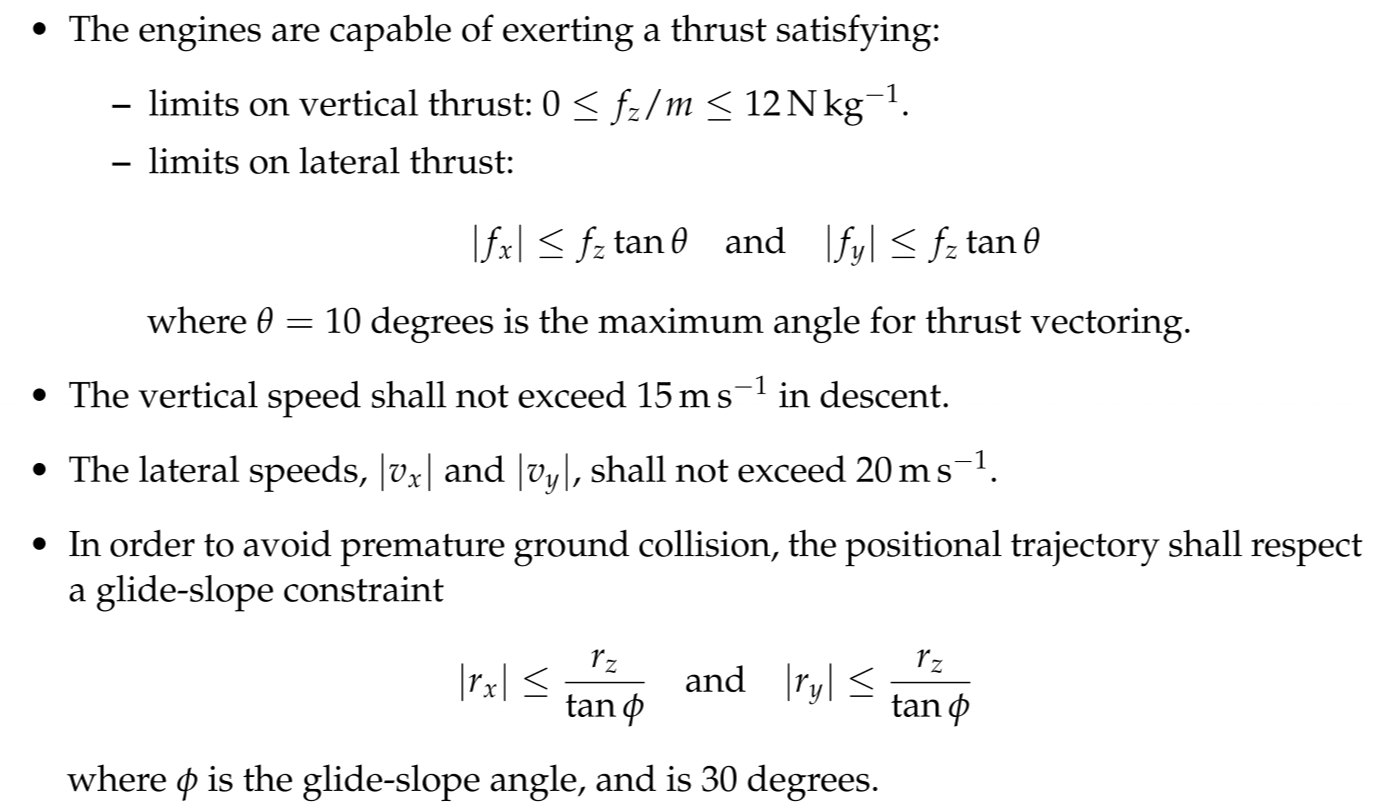

#### Target Set

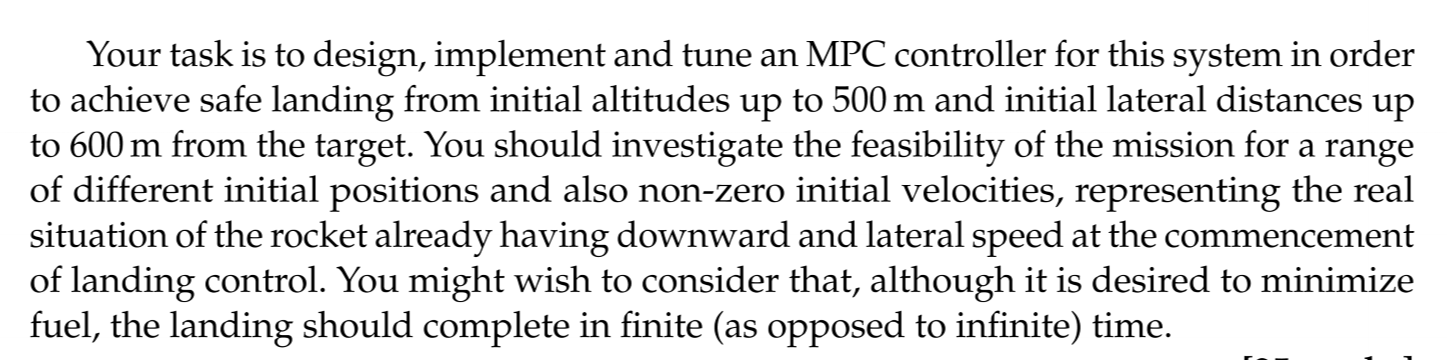

## Solution

T = 0.5;    % sampling time is 0.5s
g = 9.81;   % assuming earth gravity
m = 1;      % simplifying rocket mass

% dimensions
n = size(A,1);  % number of states
m = size(B,2);  % number of inputs
p = size(C,1);  % number of outputs

A = double(subs(A));    B = double(subs(B));

% Controllability and Observability
Rc = ctrb(A,B), rank(ctrb(A,B))

Rc =     0.0417         0         0    0.1250         0         0    0.2083         0         0    0.2917         0         0    0.3750         0         0    0.4583         0         0
         0    0.0417         0         0    0.1250         0         0    0.2083         0         0    0.2917         0         0    0.3750         0         0    0.4583         0
         0         0    0.0417         0         0    0.1250         0         0    0.2083         0         0    0.2917         0         0    0.3750         0         0    0.4583
    0.1667         0         0    0.1667         0         0    0.1667         0         0    0.1667         0         0    0.1667         0         0    0.1667         0         0
         0    0.1667         0         0    0.1667         0         0    0.1667         0         0    0.1667         0         0    0.1667         0         0    0.1667         0
         0         0    0.1667         0         0    0.1667         0         0    0.1667

ans = 6

Oc = obsv(A,C), rank(obsv(A,C))

Oc =     1.0000         0         0         0         0         0
         0    1.0000         0         0         0         0
         0         0    1.0000         0         0         0
    1.0000         0         0    0.5000         0         0
         0    1.0000         0         0    0.5000         0
         0         0    1.0000         0         0    0.5000
    1.0000         0         0    1.0000         0         0
         0    1.0000         0         0    1.0000         0
         0         0    1.0000         0         0    1.0000
    1.0000         0         0    1.5000         0         0


ans = 6


% Cost Penalty Matrix Design
Q = C'*C;   % Q needs to be equal to the size of the states
R = 1*eye(m); %R=eye(3);   % R needs to be equal to the size of the inputs
P=0*Q; %P=Q;

% Controller Horizon Length
N = 7; 

% Initial states, at rest and at (200, 200, 600)m away from the target
x0 = [350 200 500 0 0 0]'

x0 =    350
   200
   500
     0
     0
     0



% Simulation Length
nk = 100;

### Zero Control Effort Response

% Zero control effort response: 
f_x = 0; f_y = 0; f_z = 0;  f = double(subs(f)), u = f

f =          0
         0
  -29.4300


u =          0
         0
  -29.4300


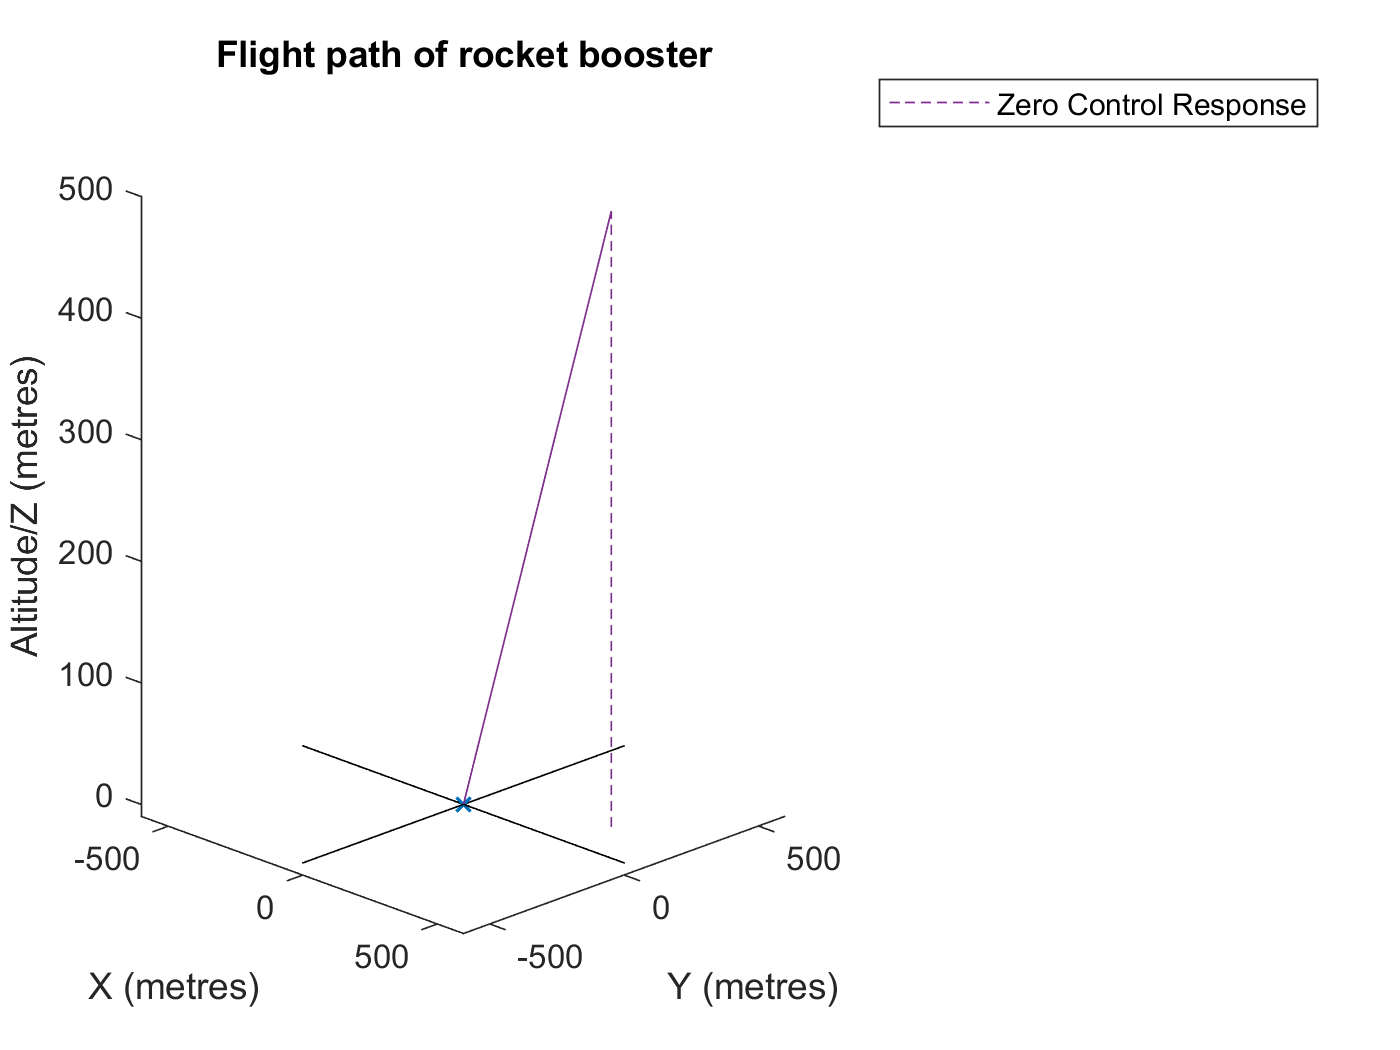


% Simulate
x = x0;
for k = 1:nk    % Safety Limit
    % get current u and y
    %u = [0 0 0]'; 
    y = C*x;
    
    % store
    ys(:,k+1) = y;  
    us(:,k+1) = u; 
    xs(:,k+1) = x;
    
    % move
    x = A*x + B*f;
end
xs = [x0 xs];

figure(1);
h(1) = plot3(0,0,0,'x', "LineWidth",1);                            
hold on;    set( get( get( h(1), 'Annotation'), 'LegendInformation' ), 'IconDisplayStyle', 'off' );
h(2) = plot3([0 0],[-600 600],[0 0], 'Color', 'black', "LineWidth",.5);   
hold on;    set( get( get( h(2), 'Annotation'), 'LegendInformation' ), 'IconDisplayStyle', 'off' );
h(3) = plot3([-600 600],[0 0],[0 0], 'Color', 'black', "LineWidth",.5);   
hold on;    set( get( get( h(3), 'Annotation'), 'LegendInformation' ), 'IconDisplayStyle', 'off' );

plot3(xs(1,:), xs(2,:), xs(3,:), "--", 'DisplayName', "Zero Control Response"); hold on; %legend show
xlabel("X (metres)");           %xlim([-200 200]);   %xticks([0 xs(1,1)]);
ylabel("Y (metres)");           %ylim([-200 200]);   %yticks([0 xs(2,1)]);
zlabel("Altitude/Z (metres)");  zlim([-10 500]);     %zticks([0 xs(3,1)]);
view(45,15);    title("Flight path of rocket booster"); legend show

### Receding-Horizon Constrained LQ-MPC

% Mode-2 K and P
K = -dlqr(A,B,Q,100*R); %K = [1.5 -1];
P = dlyap((A+B*K)',Q + K'*R*K);

#### Input and State Constraint Matrices:

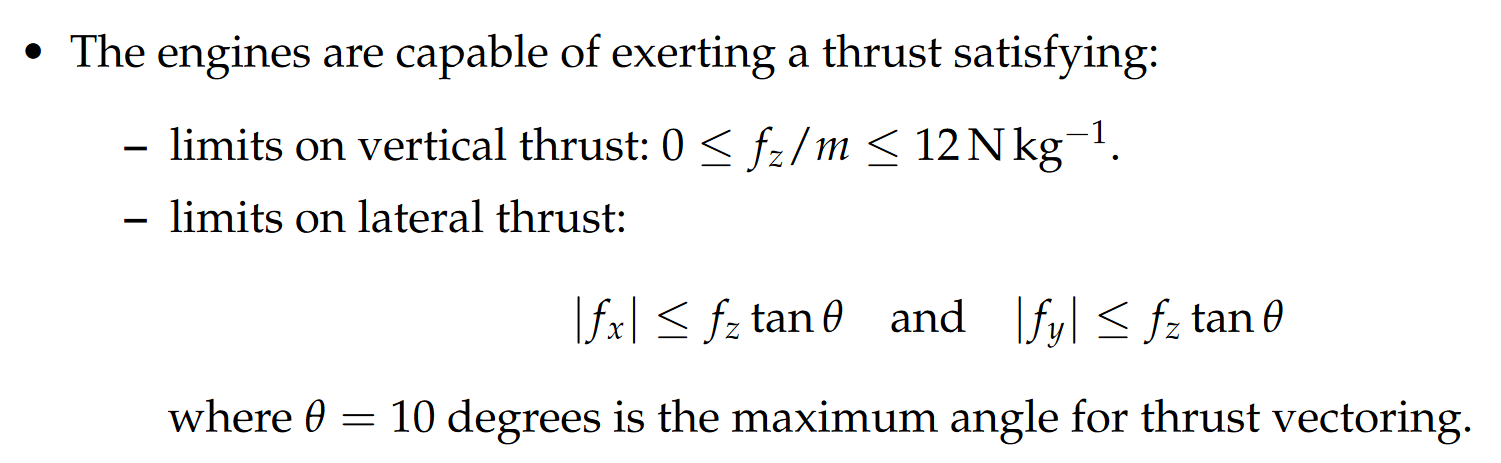

theta_max = 10;
fz_max = 12*m;

qu = [  % Input constraints
    fz_max*tan(theta_max);  % f_x Upper limit
    fz_max*tan(theta_max);  % f_y Upper limit
    fz_max-g*m; % f_z Upper limit (subtracting gravity acting downwards)
    fz_max*tan(theta_max);  % f_x Lower limit
    fz_max*tan(theta_max);  % f_y Lower limit
    0+g*m;      % f_z Lower limit (zero thrust, gravity acting downwards)
    ], Pu = [+eye(m); -eye(m);]   

qu =    23.3410
   23.3410
    6.5700
   23.3410
   23.3410
   29.4300


Pu =      1     0     0
     0     1     0
     0     0     1
    -1     0     0
     0    -1     0
     0     0    -1


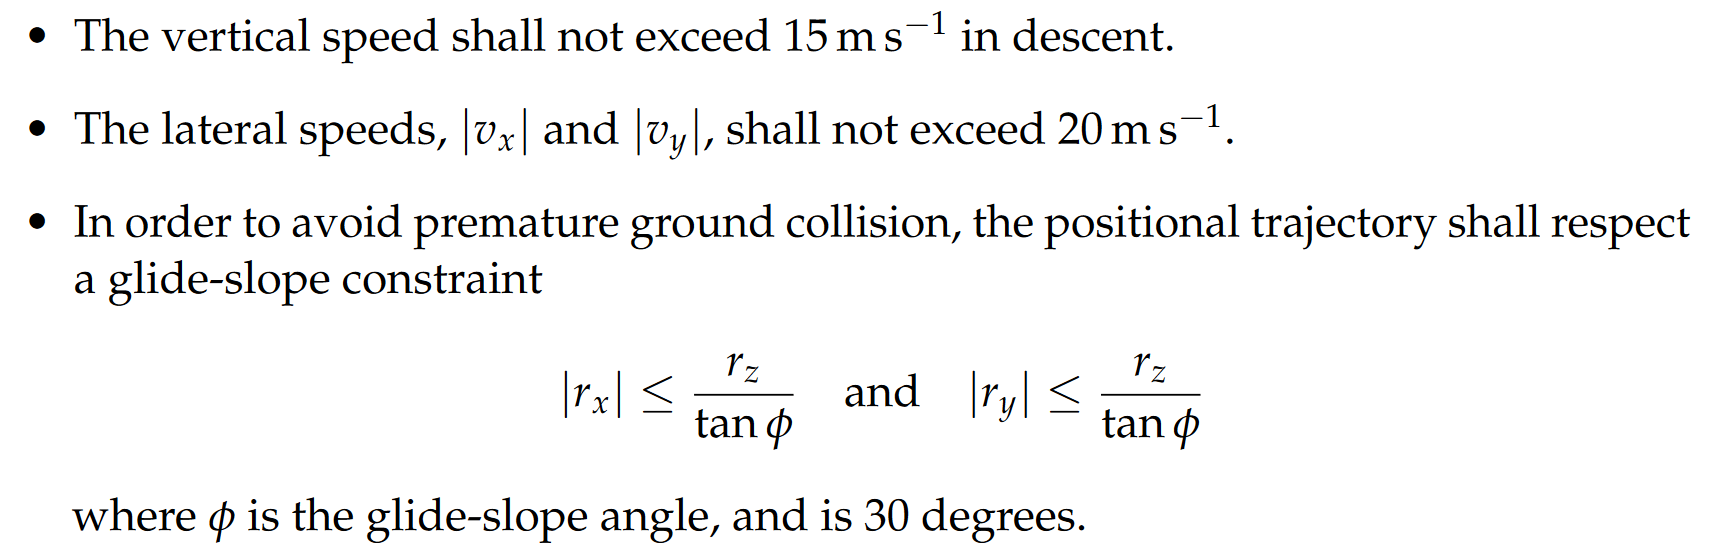

Glide-slope angle constraint is not currently implemented

qx = [  % State Constraints
    inf;    % X position Upper limit
    inf;    % Y position Upper limit
    inf;    % Z position Upper limit
    20;     % "the lateral speeds, |vx| and |vy|, shall not exceed 20 m s−1"
    20;     %  ^^^
    inf;    % no upper limit on Z velocity
    inf;    % no lower limit on X position
    inf;    % no lower limit on Y position
    0;      % the rocket cannot go beneath the ground level
    20;     % "the lateral speeds, |vx| and |vy|, shall not exceed 20 m s−1"
    20;     %  ^^^
    15;     % "the vertical speed shall not exceed 15 m s−1 in descent"
    ],  Px = [+eye(n); -eye(n);] 

qx =    Inf
   Inf
   Inf
    20
    20
   Inf
   Inf
   Inf
     0
    20


Px =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1
    -1     0     0     0     0     0
     0    -1     0     0     0     0
     0     0    -1     0     0     0
     0     0     0    -1     0     0


% qxf = [ % Terminal State Constraints
%     inf;    % X position Upper limit
%     inf;    % Y position Upper limit
%     inf;    % Z position Upper limit
%     inf;    % X velocity Upper limit
%     inf;    % Y velocity Upper limit
%     inf;    % Z velocity Upper limit
%     inf;    % X position Lower limit
%     inf;    % Y position Lower limit
%     inf;    % Z position Lower limit
%     inf;    % X velocity Lower limit
%     inf;    % Y velocity Lower limit
%     inf;    % Z velocity Lower limit
%     ];  Pxf = [+eye(n); -eye(n);]    

% build the controller
[F, G] = predict_mats(A,B,N);                               % prediction matrices
[H, L, M] = cost_mats(F,G,Q,R,P);                           % cost matrices
[Pc, qc, Sc] = constraint_mats(F,G,Pu,qu,Px,qx,Px,qx);      % Constraint matrices
% ^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^ put constraints in form Pc*U <= qc + Sc*x

% initialize
x = x0;
%ys = [C*x0 ys];
xs = zeros(n,nk);
ys = zeros(p,nk);
us = zeros(m,nk);

% loop
for k = 1:nk
    % solve optimization problem
    [Uopt, fval, flag] = quadprog(H,L*x,Pc,qc+Sc*x); % Solves optimum at each time step
    
    % get uopt
    uopt = Uopt(1:m,:); % extracts the first input in the sequence for each state
    
    % store
    us(:,k) = uopt;
    xs(:,k) = x;
    ys(:,k) = C*x;
    
    % move forward one time step
    x = A*x + B*uopt;
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

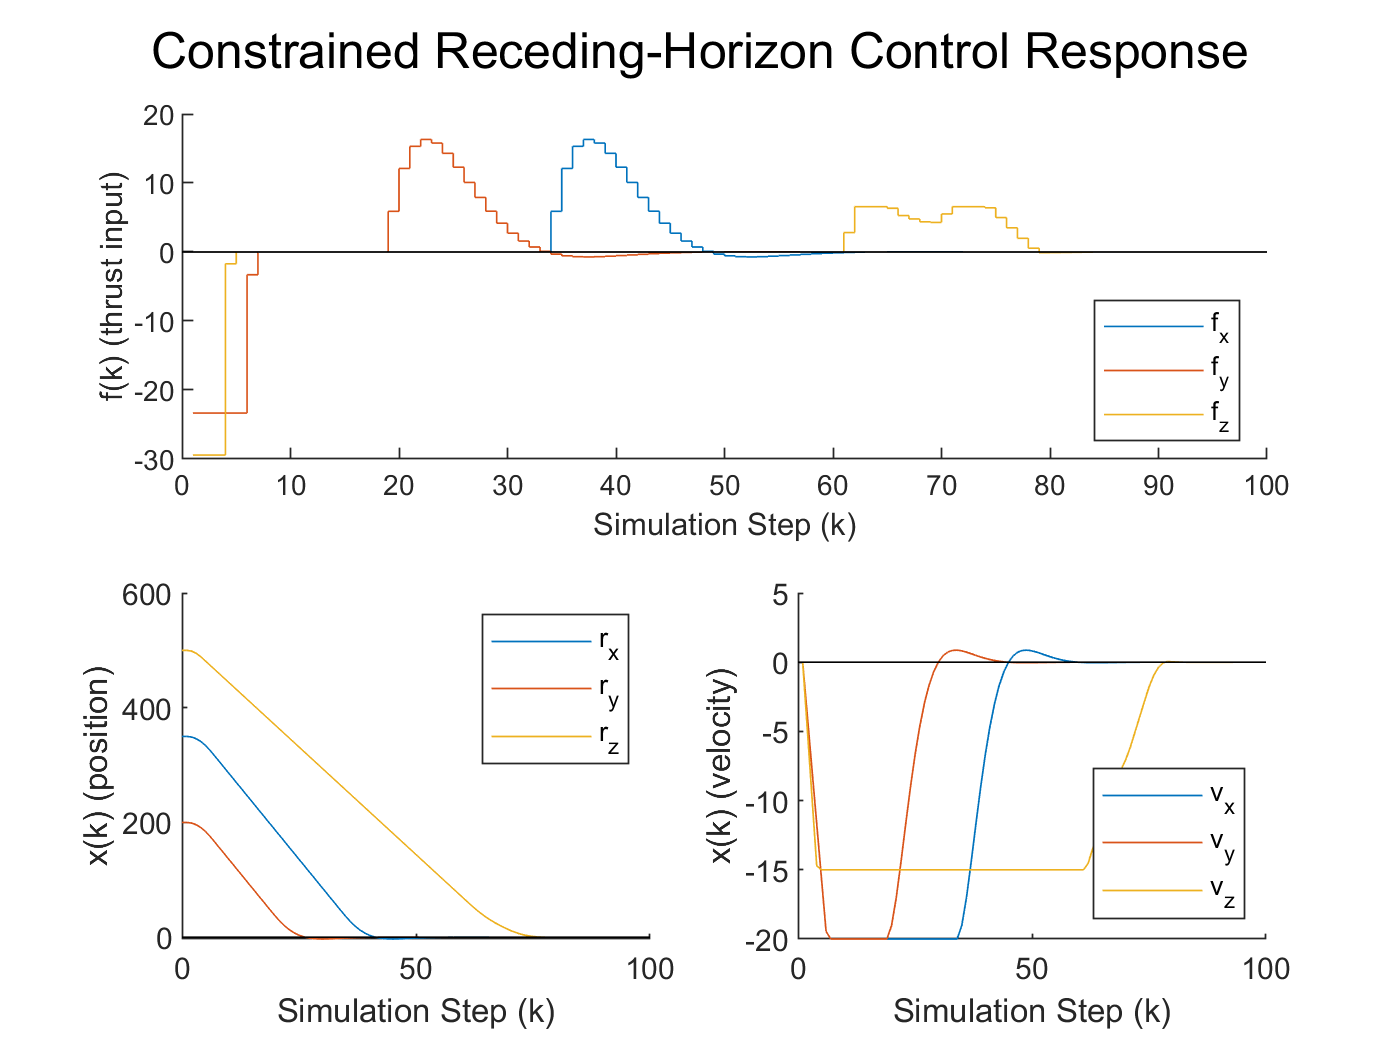

xs = [x0 xs];

figure(7); sgtitle("Constrained Receding-Horizon Control Response");
% Plot results
subplot(2,2,[1 2]); hold on
stairs([1:nk], us(1,:));   % plot of input and input constraints
stairs([1:nk], us(2,:));
stairs([1:nk], us(3,:));
%ylim([min(qu) max(qu)]);
subplot(2,2,3); hold on
plot([0:nk], xs(1,:));     % plot of position states
plot([0:nk], xs(2,:));
plot([0:nk], xs(3,:));
subplot(2,2,4); hold on
plot([0:nk], xs(4,:));     % plot of velocity states
plot([0:nk], xs(5,:));
plot([0:nk], xs(6,:));

% Plot annotations
subplot(2,2, [1 2]);    ylabel("f(k) (thrust input)");    xlabel("Simulation Step (k)");  
legend("f_x","f_y","f_z",'Location', 'southeast')
h = plot([0 nk],[0 0], 'Color', 'black', "LineWidth",.5);
hold on;    set( get( get( h, 'Annotation'), 'LegendInformation' ), 'IconDisplayStyle', 'off' );
subplot(2,2,3);         ylabel("x(k) (position)");  xlabel("Simulation Step (k)"); 
legend("r_x","r_y","r_z",'Location', 'northeast')
h = plot([0 nk],[0 0], 'Color', 'black', "LineWidth",.5);
hold on;    set( get( get( h, 'Annotation'), 'LegendInformation' ), 'IconDisplayStyle', 'off' );
subplot(2,2,4);         ylabel("x(k) (velocity)");  xlabel("Simulation Step (k)");  
legend("v_x","v_y","v_z",'Location', 'southeast')
h = plot([0 nk],[0 0], 'Color', 'black', "LineWidth",.5);
hold on;    set( get( get( h, 'Annotation'), 'LegendInformation' ), 'IconDisplayStyle', 'off' );

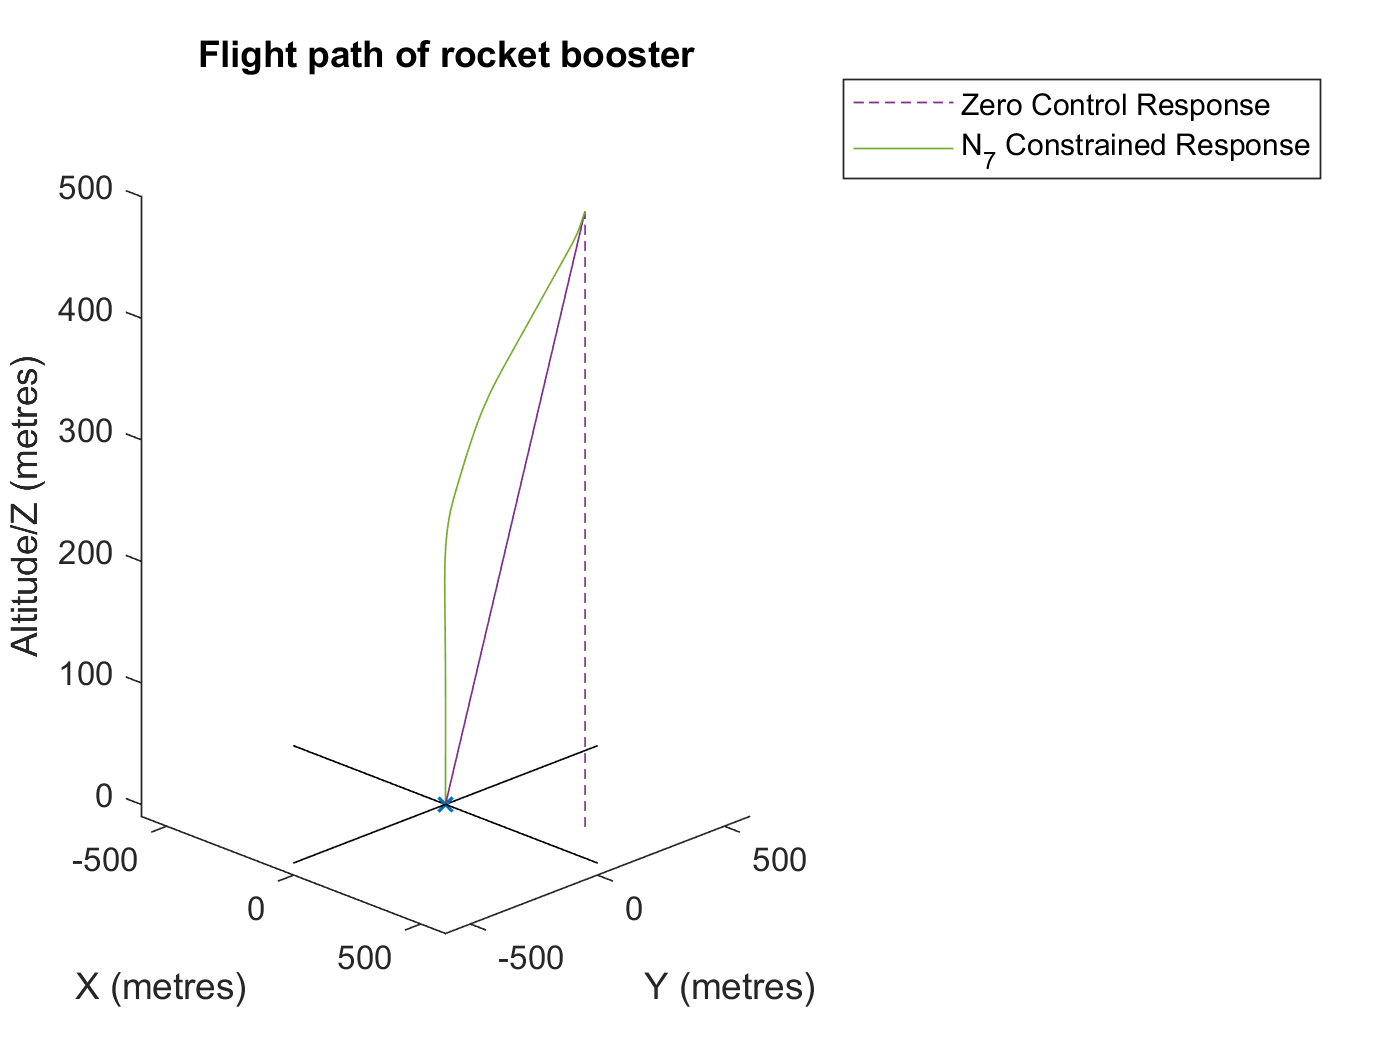


figure(1);  plot3(xs(1,:), xs(2,:), xs(3,:), '-', 'DisplayName', "N_"+N+" Constrained Response"); hold on

## Functions

### Terminal Constraint Matrices

function [E, D] = terminal_constraint_mats(G, F, n, N)

    Px = zeros(n);    
    for ii = 2:N-1
        Px = [Px, zeros(n)];
    end
    Px = [Px, eye(n)];
    
    E = Px*G;
    D = Px*F;
end